Consider a viscous fluid that moves along a pipe of rectangular section that is $L = 10$ cm deep. Assuming that the pressure drop in the pipe is $180$ N/m$^{2}$ per meter, we want to find the velocity profile $u(y)$ of the fluid. The velocity profile satisfies the equation


$$-\frac{\mathrm{d}}{\mathrm{d} u}\left(\mu(y)\frac{\mathrm{d} u}{\mathrm{d} y}\right) = 180,$$


where the viscosity $\mu(y)$ of the fluid is a function that is constant on each element, according to the following table:


$$\begin{array}{rrrrrr}
\text{Element} & \Omega_{1} & \Omega_{2} & \Omega_{3} & \Omega_{4} & \Omega_{5}\\ \hline
\mu\: \text{(kg/m/s)} & 0.59 & 0.49 & 0.31 & 0.29 & 0.16 \\ \hline
\end{array}$$


Assume that the profile is meshed with $5$ equal linear elements as shown in the Figure. The fluid sticks to the walls of the pipe, imposing boundary conditions $u(y_{1} ) = u(y_{6}) = 0$where $y_{1}$ and $y_{6}$ are the first and the last nodes.

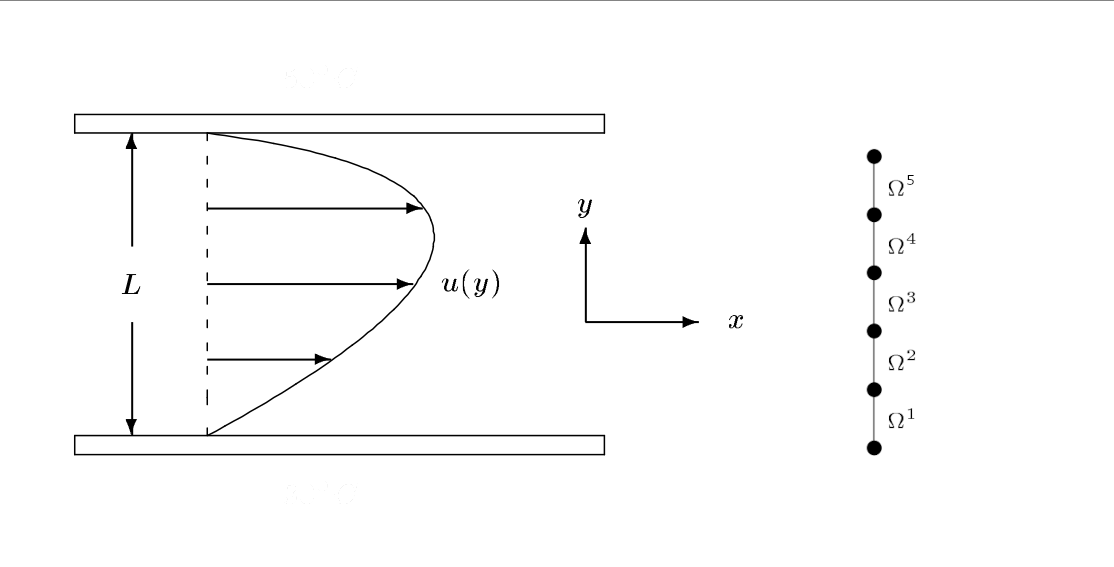

## Part (a)

(a) (2 points) The value $K^{1}_{1,1}$ is:

$\bullet$ 29.5000 ✅

$\bullet$ Empty answer (no penalty)

$\bullet$ 26.5000

$\bullet$ 27.5000

$\bullet$ 31.5000

$\bullet$ 28.5000

**Hint: **$K^{1}_{1,1} = 24.5000$

### Solution

clearvars
close all

%
% Data
% -------------------------------------------------------------------------------------------------------------------
a1 = [0.59, 0.49, 0.31, 0.29, 0.16]; %question 1
%a1 = [0.53, 0.43, 0.35, 0.30, 0.20]; %question 2
%a1 = [0.60, 0.50, 0.40, 0.25, 0.18]; %question 3
%a1 = [0.54, 0.44, 0.39, 0.28, 0.20]; %question 4
%a1 = [0.50, 0.40, 0.38, 0.29, 0.17]; %question 5
%a1 = [0.57, 0.47, 0.34, 0.27, 0.12]; %question 6

L = 0.10;  %m

f = 180.0; %N / m^2, question 1
%f = 110.0; %N / m^2, question 2
%f = 120.0; %N / m^2, question 3
%f = 110.0; %N / m^2, question 4
%f = 170.0; %N / m^2, question 5
%f = 180.0; %N / m^2, question 6

numNodes = 6;

pointP = L / 2;
pointHint = L / 4;

a = 0; b = L;
% -------------------------------------------------------------------------------------------------------------------

nodes = linspace(a,b,numNodes);
elem = [1:numNodes-1; 2:numNodes]';
numElem = size(elem,1); h = (b-a) / numElem;

fprintf(['(a) K^1_{1,1} = %.4f\n',...
         '    Hint: K^2_{1,1} = %4f\n'], a1(1) / h, a1(2) / h)

(a) K^1_{1,1} = 29.5000
    Hint: K^2_{1,1} = 24.500000


## Part (b)

(6 points) The maximum velocity $u(y_{i})$ among all nodes $y_{i}$ is:

$\bullet$ 0.6367 *m/s*

$\bullet$ 0.7074 *m/s *✅

$\bullet$ 0.6225 *m/s*

$\bullet$ Empty answer (no penalty)

$\bullet$ 1.3371 *m/s*

$\bullet$ 0.6296 *m/s*

**Hint:** $\sum_{i = 1}^{6} u(y_{i}) = 2.2053$

### Solució

K = zeros(numNodes);
F = zeros(numNodes,1);
Q = zeros(numNodes,1);

Fe = f * h * [1; 1] / 2;

#### Assembly the stiffness matrices

for e = 1:numElem
    rows = [elem(e,1), elem(e,2)];
    cols = rows;
    Ke = a1(e) * [1, -1; -1, 1] / h;
    K(rows,cols) = K(rows, cols) + Ke;
    F(rows) = F(rows) + Fe;
end

#### Boundary conditions

%Boundary conditions
fixedNodes = [1, 6];
freeNodes = setdiff(1:numNodes, fixedNodes);

#### Natural Boundary conditions

%Natural B.C.:
Q(freeNodes) = 0.0; %Not necessary, since vector Q was initialised to 0


#### Essential Boundary conditions

%Essential B.C.:
u = zeros(numNodes,1);
u(1) = 0.0;
u(6) = 0.0;

#### Reduced system

%Reduced system
Fm = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes); %Not necessary, since u(fixedNodes) = 0;
Km = K(freeNodes,freeNodes);

#### Soluition of the reduced system

%Solution of the reduced system
um = Km \ Fm;
u(freeNodes) = um;

fprintf(['(b) Maximum velocity among all the nodes: %.4f m/s\n', ...
         '    Hint; Sum(u) = %.4f\n'] , max(u), sum(u))

(b) Maximum velocity among all the nodes: 0.7074 m/s
    Hint; Sum(u) = 2.2053


## Part (c) 

(2 points) interpolate the solution values $u(y_{i})$ using a function $p(y_{i}) = \sum_{i = 0}^{5} c_{i} y^{i}$. Evaluate $p(y)$ at half the depth of the pipe:

$\bullet$ 0.7168 *m/s*

$\bullet$ 0.5799 *m/s*

$\bullet$ 0.6516 *m/s *✅

$\bullet$ 1.2315 *m/s*

$\bullet$ 0.5734 *m/s*

$\bullet$Empty answer (no penalty)

**Hint:** $p(y = 0.025) = 0.3869$

### Solution

coefs = polyfit(nodes, u, 5);

fprintf(['(c) Interpolated Solution value at half the depth of the pipe, p(%.2f) = %.4f\n', ...
         '    Hint: p(%.3f) = %.4f\n'],  pointP, polyval(coefs, pointP), pointHint, polyval(coefs, pointHint))

(c) Interpolated Solution value at half the depth of the pipe, p(0.05) = 0.6516
    Hint: p(0.025) = 0.3869


Print all the solutions at once:

fprintf(['Solutions:\n',...
    '(a) K^1_11 = %.4f\n',...
    '    Hint: K^2_{1,1} = %4f\n',...
    '(b) Maximum velocity among all the nodes: %.4f m/s\n',...
    '    Hint; Sum(u) = %.4f\n',...
    '(c) Interpolated Solution value at half the depth of the pipe, p(%.2f) = %.4f\n', ...
    '    Hint: p(%.3f) = %.4f\n'],...
         a1(1) / h, a1(2) / h,...
         max(u), sum(u),...
         pointP, polyval(coefs, pointP), pointHint, polyval(coefs, pointHint))

Solutions:
(a) K^1_11 = 29.5000
    Hint: K^2_{1,1} = 24.500000
(b) Maximum velocity among all the nodes: 0.7074 m/s
    Hint; Sum(u) = 2.2053
(c) Interpolated Solution value at half the depth of the pipe, p(0.05) = 0.6516
    Hint: p(0.025) = 0.3869
